clc; clear all; close all;

#### Generating Random Data to Transmit

% Creating X_k - Randomly choose between 1 and -1
N_Training = 16; 
N_XData = 84;
Bits_per_set=64;
size_training_data = 64*N_Training;
size_X = 64*N_XData; %Size of data - 84 sets of 64 bits
range = [-1 1]; %List of wanted values
a = randi(2,size_X,1); %Randomly select index
b = randi(2,size_training_data,1); 

Create Data and Training Data

X_k = transpose(range(a)); %Creates array with range(a) values
X_train = transpose(range(b)); % Creates Training Data
message = [X_train ; X_k]; %Combines data

#### IDFT - Takes inverse discrete fourier tranform of data

x_m = ifft(message); %Turns data points into impulses

#### Adding cyclic prefix

n_data = N_Training + N_XData; % Calculates amount of sets of d-bit data chunks from original data
tx_data = [];

%Index 1st cyclic prefix - Done to ensure methodology works
cycPrefix = x_m(49: 64);                  % Determines index of first cyclic prefix - 16 bits
tx_data(1:16) = cycPrefix;                % Initializes array that will hold data w/ prefix
tx_data(17:80) = x_m(1: 64);             % Loads first set of data  -  64 bits

%Index the Remaining Data
for R = 2:1:n_data  % Adds cyclic prefixes
    cycPrefix = x_m(64*(R-1)+ 48+1: 64*(R));
    tx_data(1 + 80*(R-1): 16*R + 64*(R-1)) = cycPrefix;
    Post_chunk =  x_m(64*(R-1)+1: 64*(R));
    tx_data(1 + 16*R + 64*(R-1) : 16*R + 64*R) = Post_chunk;
end
tx_data = transpose(tx_data)

tx_data =   -0.0063 - 0.0032i
   0.0049 - 0.0000i
  -0.0107 - 0.0140i
  -0.0081 + 0.0181i
   0.0010 + 0.0139i
  -0.0013 + 0.0008i
  -0.0054 + 0.0054i
  -0.0012 - 0.0059i
  -0.0093 + 0.0070i
   0.0041 + 0.0097i


#### Transmitting Data through nonflat channel function

Transmitting Training Data

% Transmit data through nonflat channel function
rx_data = nonflat_channel((tx_data));

Compensating for time delay

% Determine Lag in Data
[y1x1,lag1] = xcorr(rx_data,tx_data); 
[~, Index] = max(abs(y1x1));
shift1_train = lag1(Index); %SHould be 9

%Remove Extra Data
rx_data = rx_data(shift1_train:length(tx_data)+shift1_train-1); %Should be 8000 bits

Estimate Channel: Estimating channel for each set of 64 bits using the Training Data

H = zeros(64,1);

%Obtain Training Data
Size_PC = 16;
Size_Training_PC = Size_PC*N_Training + N_Training*Bits_per_set; %1280 Bits

for G = 1:1:64  % Adds cyclic prefixes
    Data_N = rx_data(G:64:Size_Training_PC);
    Channel_estimate = Data_N./x_m(G);
    H(G) = mean(Channel_estimate);
end

Convolution

% for Z = 1:1:n_data
%     Conv_data = conv(rx_data, H);
% end

Decode

X_k_est = zeros(length(message),1);
for Z = 1:1:n_data
    X_est = fftshift(fft(rx_data(1 + 64*(Z-1):64*Z)));
    X_est=X_est./H;
    X_k_est(1 + 64*(Z-1):64*Z) = X_est;
end

Plot X_est

Norm_ret = real(X_k_est) ./ abs(real(X_k_est))

Norm_ret =      1
     1
    -1
     1
     1
     1
    -1
    -1
    -1
     1


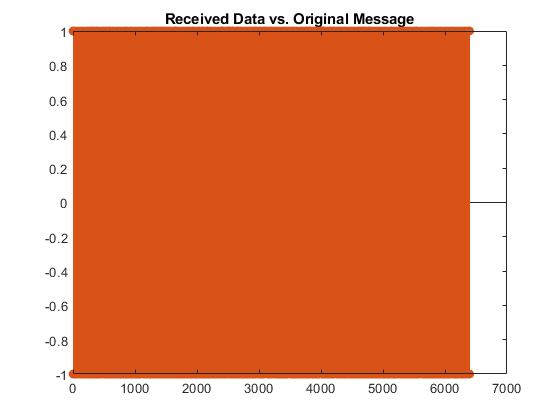


figure;
stem(real(Norm_ret));
hold on
stem(real(message));
title('Received Data vs. Original Message')
hold off

#### Transmitted Vs Received Data

% Calculating Error
diff = (message - Norm_ret)./(2*message);
Error = abs(mean(diff)) *100

Error = 50.6406

Channel Estimation 

With OFDM, we are assuming flat fading model for every 64 bits of data, giving us 100 different transfer functions

% H_k = zeros(100,1); %Empty vector to put transfer function values
% 
% for H = 1:1:n_data   % For each chunk of 64 -> 100 in total
%     ChannelEst_n = mean(Y_k(1 + 64*(H-1): 64*(H))); % Calculates transfer function for every 64 bits (assuming flat fading model)
%     H_k(H) = ChannelEst_n; %Place data into Transfer function matrix
% end
% figure;
% stem(real(H_k));
% hold on
% title('Transfer Functions of Data');
% hold off
% 

Estimation of Noise

% est_noise = var(noise_thru_channel)
% 
% for Z = 1:1:n_data   % For each chunk of 64 -> 100 in total
%     w = ((conj(H_k(Z))));
%     Y_ret = (conj(w)).*(Y_k(1 + 64*(Z-1): 64*(Z))); % Calculates transfer function for every 64 bits (assuming flat fading model)
%     Retrieved_data(1 + 64*(Z-1): 64*(Z)) = Y_ret; %Place data into Transfer function matrix
% end
Retrieved_data = transpose(Retrieved_data)

Unrecognized function or variable 'Retrieved_data'.

Estimate Channel Impulse Response

% Alpha_z = zeros(640,1);
% Impulse = ones(1,1);
% Beta_z = zeros(640,1);
% 
% Impulse_signal = [Alpha_z ; Impulse ; Beta_z]
% impulseresponse = nonflat_channel(Impulse_signal)
% impulseresponse = impulseresponse(649:660)
% figure;
% stem(impulseresponse,'*')
% hold on
% title('Impulse Response of System')
% xlabel('Time (s)');
% ylabel('Amplitude');
% ylim([-.3,1]);
% hold off

Circular Convolution

% rx_conv = conv(impulseresponse, rx_data)
% stem(rx_conv)

Realign

% % Determine Lag in Data
% [y1x1,lag1] = xcorr(rx_conv, rx_data); 
% [~, Index] = max(abs(y1x1));
% shift2 = lag1(Index)
% %Comes out to be 9
% 
% %Cut Data from Lag
% rx_data = rx_data(shift2:end);